# Illustrating Three Approaches to GPU Computing

**Source: **[https://de.mathworks.com/help/parallel-computing/examples/illustrating-three-approaches-to-gpu-computing-the-mandelbrot-set.html](https://de.mathworks.com/help/parallel-computing/examples/illustrating-three-approaches-to-gpu-computing-the-mandelbrot-set.html)

## Login to Andie

## Setup

clear; clc; 
maxIterations = 50000;
gridSize = 1000;
xlim = [-0.748766713922161, -0.748766707771757];
ylim = [ 0.123640844894862,  0.123640851045266];


## The Mandelbrot Set in MATLAB

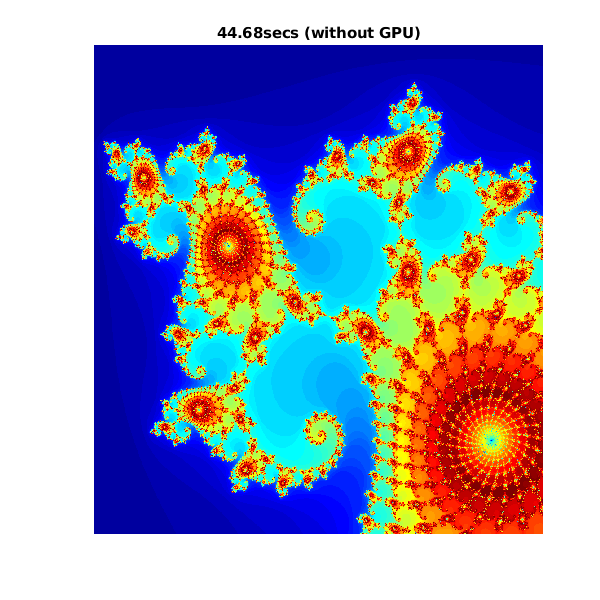

% Setup
t = tic();
x = linspace( xlim(1), xlim(2), gridSize );
y = linspace( ylim(1), ylim(2), gridSize );
[xGrid,yGrid] = meshgrid( x, y );
z0 = xGrid + 1i*yGrid;
count = ones( size(z0) );

% Calculate
z = z0;
for n = 0:maxIterations
    z = z.*z + z0;
    inside = abs( z )<=2;
    count = count + inside;
end
count = log( count );

% Show
cpuTime = toc( t );
fig = gcf;
fig.Position = [200 200 600 600];
imagesc( x, y, count );
colormap( [jet();flipud( jet() );0 0 0] );
axis off
title( sprintf( '%1.2fsecs (without GPU)', cpuTime ) );

## Using gpuArray

When MATLAB encounters data on the GPU, calculations with that data are performed on the GPU. The class gpuArray provides GPU versions of many functions that you can use to create data arrays, including the linspace, logspace, and meshgrid functions needed here. Similarly, the count array is initialized directly on the GPU using the function ones.

With these changes to the data initialization the calculations will now be performed on the GPU:

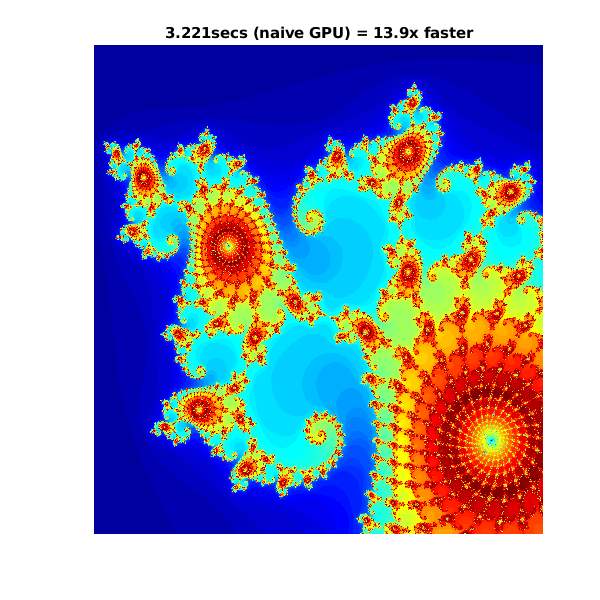

% Setup
t = tic();
x = gpuArray.linspace( xlim(1), xlim(2), gridSize );
y = gpuArray.linspace( ylim(1), ylim(2), gridSize );
[xGrid,yGrid] = meshgrid( x, y );
z0 = complex( xGrid, yGrid );
count = ones( size(z0), 'gpuArray' );

% Calculate
z = z0;
for n = 0:maxIterations
    z = z.*z + z0;
    inside = abs( z )<=2;
    count = count + inside;
end
count = log( count );

% Show
count = gather( count ); % Fetch the data back from the GPU
naiveGPUTime = toc( t );
imagesc( x, y, count )
axis off
title( sprintf( '%1.3fsecs (naive GPU) = %1.1fx faster', ...
    naiveGPUTime, cpuTime/naiveGPUTime ) )

## **Element-wise Operation**

Noting that the algorithm is operating equally on every element of the input, we can place the code in a helper function and call it using arrayfun. For GPU array inputs, the function used with arrayfun gets compiled into native GPU code. In this case we placed the loop in **pctdemo_processMandelbrotElement.m:**

Note that an early abort has been introduced because this function processes only a single element. For most views of the Mandelbrot Set a significant number of elements stop very early and this can save a lot of processing. The for loop has also been replaced by a while loop because they are usually more efficient. This function makes no mention of the GPU and uses no GPU-specific features - it is standard MATLAB code.

Using arrayfun means that instead of many thousands of calls to separate GPU-optimized operations (at least 6 per iteration), we make one call to a parallelized GPU operation that performs the whole calculation. This significantly reduces overhead.

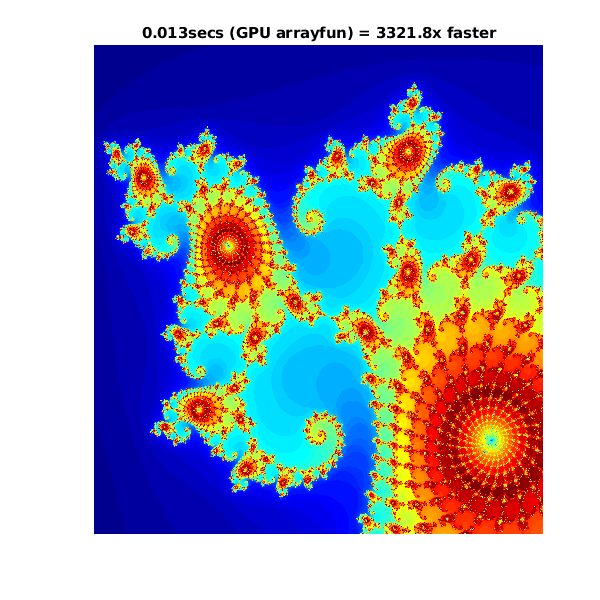

% % Setup
t = tic();
x = gpuArray.linspace( xlim(1), xlim(2), gridSize );
y = gpuArray.linspace( ylim(1), ylim(2), gridSize );
[xGrid,yGrid] = meshgrid( x, y );
 
% Calculate
count = arrayfun( @pctdemo_processMandelbrotElement, ...
                  xGrid, yGrid, maxIterations );
 
% Show
count = gather( count ); % Fetch the data back from the GPU
gpuArrayfunTime = toc( t );
imagesc( x, y, count )
axis off
title( sprintf( '%1.3fsecs (GPU arrayfun) = %1.1fx faster', ...
    gpuArrayfunTime, cpuTime/gpuArrayfunTime ) );

## Compile cuda file

setenv('MW_NVCC_PATH','/usr/local/cuda/bin')
!nvcc -ptx pctdemo_processMandelbrotElementCU.cu

## Working with CUDA

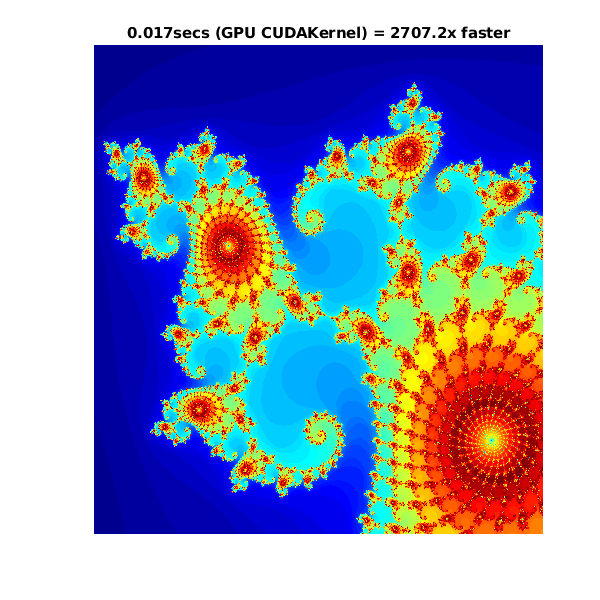

% % Load the kernel
cudaFilename = 'pctdemo_processMandelbrotElementCU.cu';
ptxFilename = 'pctdemo_processMandelbrotElementCU.ptx';

kernel = parallel.gpu.CUDAKernel( ptxFilename, cudaFilename );
 
% % Setup
t = tic();
x = gpuArray.linspace( xlim(1), xlim(2), gridSize );
y = gpuArray.linspace( ylim(1), ylim(2), gridSize );
[xGrid,yGrid] = meshgrid( x, y );
 
% Make sure we have sufficient blocks to cover all of the locations
numElements = numel( xGrid );
kernel.ThreadBlockSize = [kernel.MaxThreadsPerBlock,1,1];
kernel.GridSize = [ceil(numElements/kernel.MaxThreadsPerBlock),1];
 
% Call the kernel
count = zeros( size(xGrid), 'gpuArray' );
count = feval( kernel, count, xGrid, yGrid, maxIterations, numElements );
 
% % Show
count = gather( count ); % Fetch the data back from the GPU
gpuCUDAKernelTime = toc( t );
imagesc( x, y, count )
axis off
title( sprintf( '%1.3fsecs (GPU CUDAKernel) = %1.1fx faster', ...
     gpuCUDAKernelTime, cpuTime/gpuCUDAKernelTime ) );